# **HW2 Program Assignment** 

**By: 105022204 吳大均 **

## Problem 1

###  Let 𝑥[𝑛] = ℎ[𝑛] = (0.9) 𝑛𝑢[𝑛] and 𝑦[𝑛] = 𝑥[𝑛] ∗ ℎ[𝑛]

### (a)    Determine 𝑦[𝑛] analytically and plot the first 99 non-zero samples using the stem function

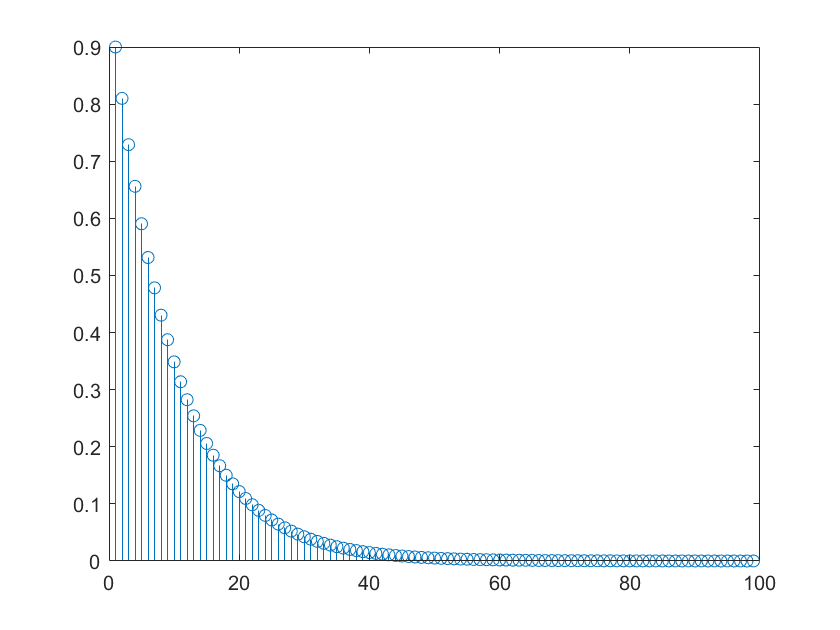

for i=1:99
    x(i)=1*0.9^(i);
    h(i)=x(i);
    if abs(x(i)) <= eps
        x(i)=0;
    end
end
x(x==0) = [];
stem(x)

### (b)    Take first 50 samples of 𝑥[𝑛] and ℎ[𝑛]. Compute and plot 𝑦[𝑛] using the conv function

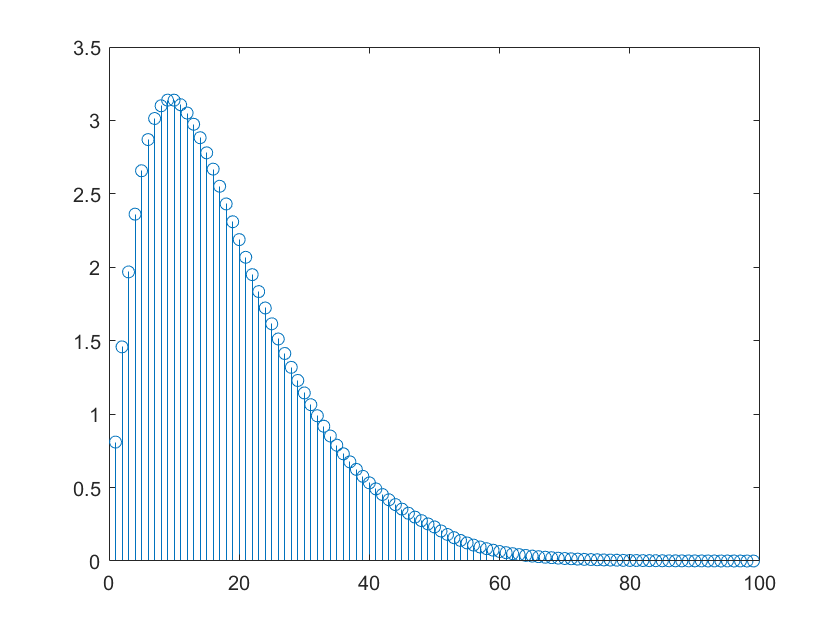

 y= conv(x(1:50),h(1:50));
 stem(y)

### (c)    Using the filter function, determine and plot the first 99 samples of 𝑦[𝑛].

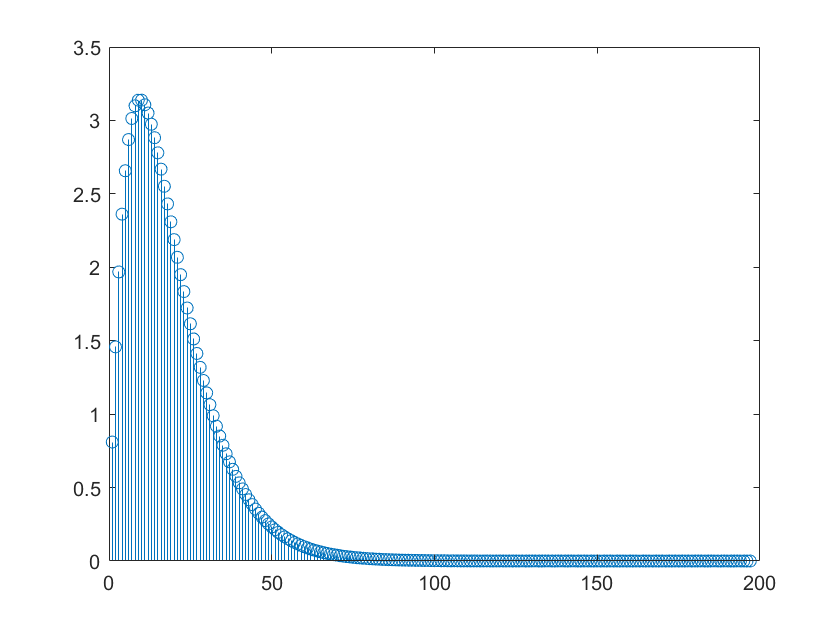

y= conv(x(1:99),h(1:99));
%% filter design
windowSize = 30; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;
%% no filter
stem(y)

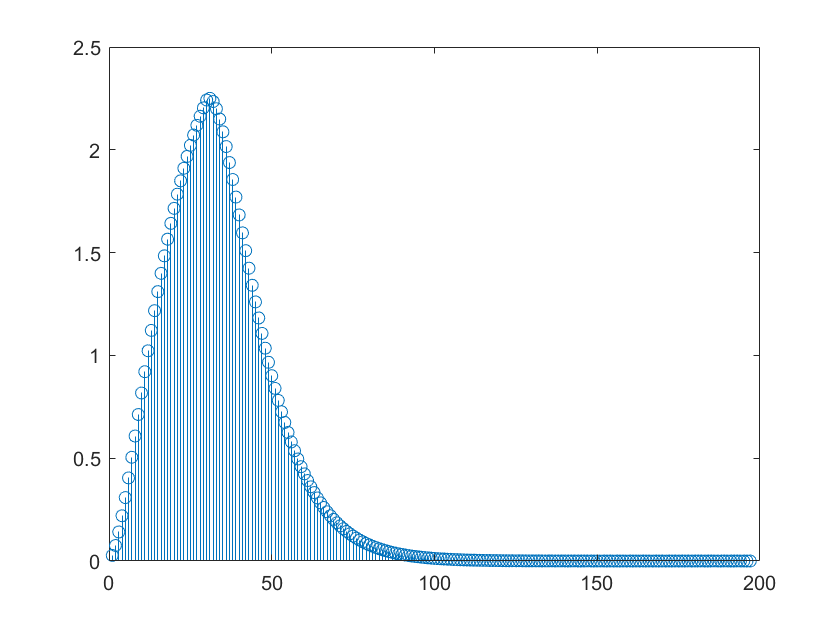

%% filter signal
y_fil = filter(b,a,y);
stem(y_fil)

### (d)    Which of the outputs in (b) and (c) come close to that in (a)? Explain.

### //

### i think (b) is more close because (c) is filtered by matlab's filter , easy to understand.

## Problem 2

### (a) area

clear;
x=sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101); 
h=ones(1,5);
y_sum=sum(x)*sum(h)

y_sum = -2.2388

### (b) 


y_conv=conv(x,h);
sum(y_conv)

ans = -2.2388

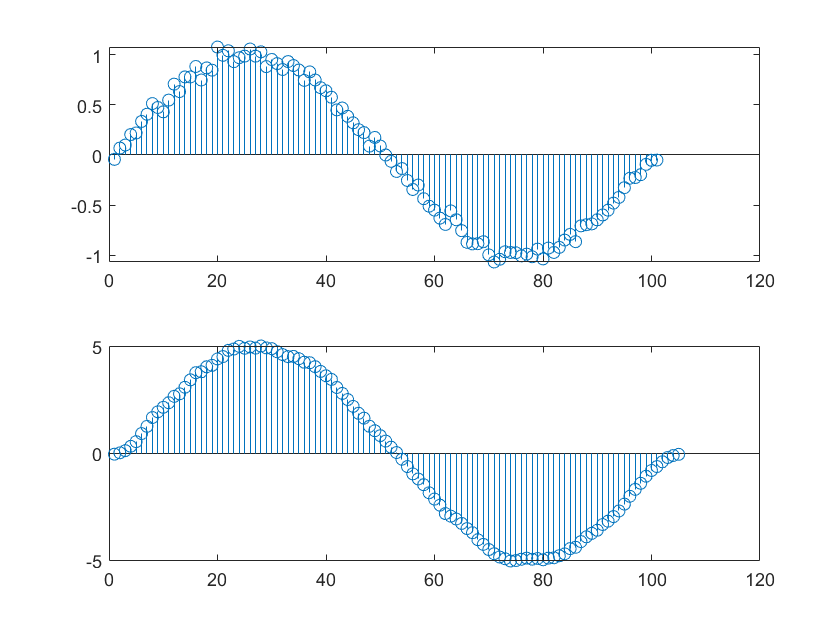

subplot(2,1,1)
stem(x)
subplot(2,1,2)
stem(y_conv)

### (c)

h=1;

y_conv=conv(x,h);
sum(y_conv)

ans = -0.4478

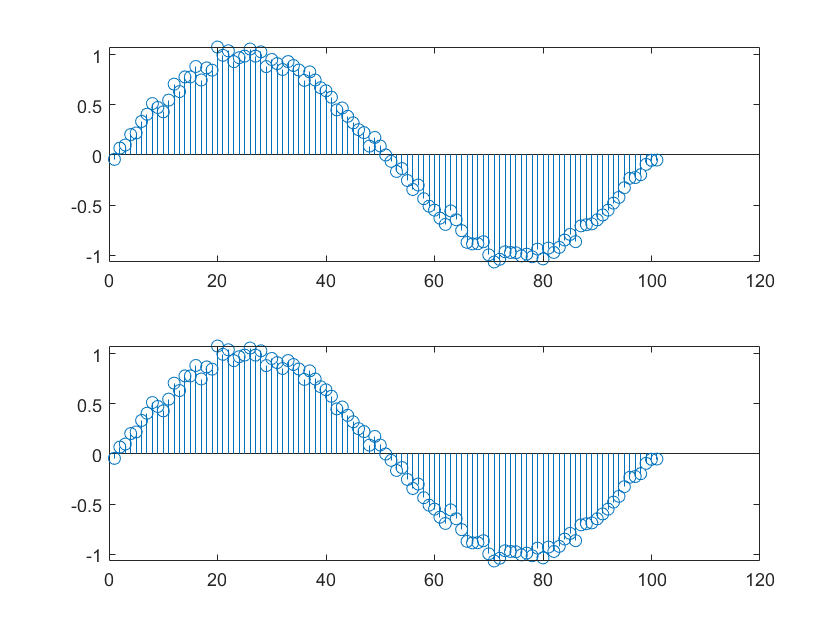


subplot(2,1,1)
stem(x)
subplot(2,1,2)
stem(y_conv)

### (d)    from (b) and (c) you can see that the noise is eliminate by convolution filter 

###         but when you choose h=1 the noise still in the signal

## Problem 3

### (a)    The response of a LTI system to the input 𝑥[𝑛] = 𝑢[𝑛] is 𝑦[𝑛] = 2 ⋅ ( 1 3 ) 𝑛𝑢[𝑛].

clear;
clf;
for i=1:20
    y_3(i)=((1/3)^(i))*2;
end





### (b)    Plot the pole-zero pattern using the function zplane(b, a)

### (c)    Compute and plot the impulse response using the functions filter and stem. 

###         Compare with the plot obtained using the function impz

### (d)    Use the function residuez and the z-transform pairs in Table 3.1 to find an analytical expression for the impulse response h[n]

## Problem 4

### Find the impulse response of the system (3.97) for the case of real and equal poles and use the result to determine how the location of the poles affects (a) the stability of the system

### (b) the shape of the impulse response. (Hint: Use MATLAB to replicate Figure 3.10 for a double pole, find C and discuss stability of the three cases |𝑎1| < 𝐶, |𝑎1| = 𝐶, |𝑎1| > 𝐶)

## Problem 5  LCCDE

### (a) 


%verify

### (b) 



%verify

## Problem 6

### (a) DFT handmade

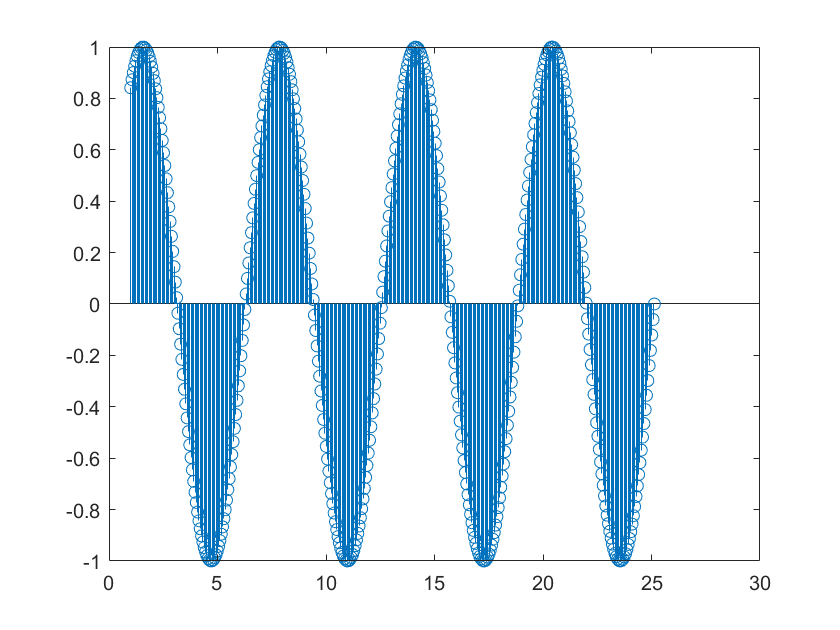

% here i build a sin signal for test the dft design
clear;
clf;
x=linspace(1,8*pi,400);
y_sin=sin(x);
stem(x,y_sin)

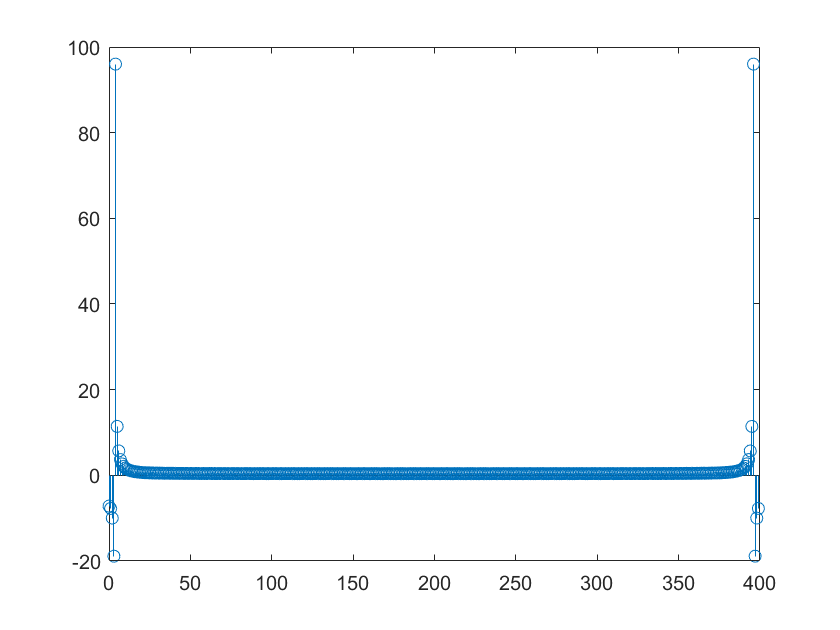

[X,t]=dtfs0(y_sin);

stem(t,X)

### (b)    iDFT handmade

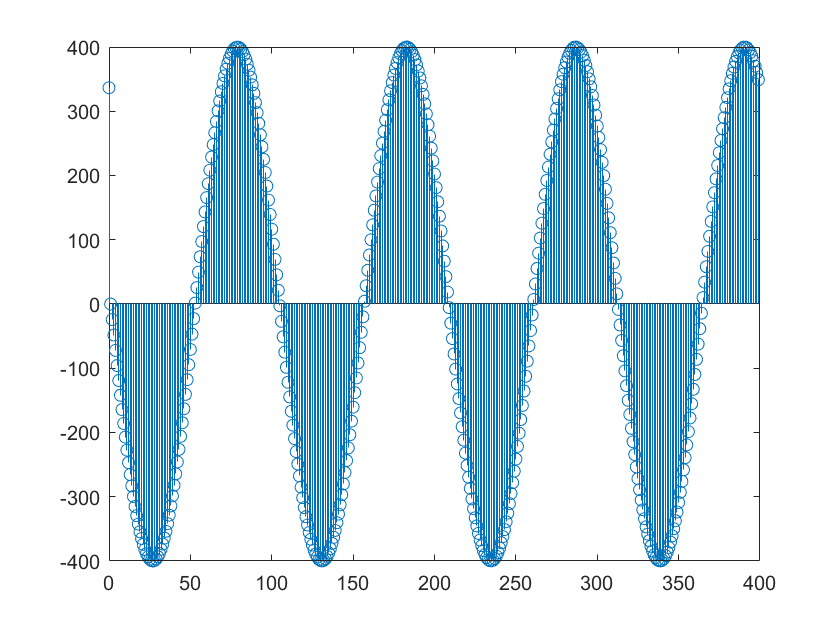

[X_idft,t]=dtfs0(X);
stem(t,X_idft)

### fine~ i think it works

## Problem 7     Determine and plot the magnitude and phase spectra of the following periodic sequences

### (a)    x1[n] = 4 ⋅ cos(1.2πn + π 3 ) + 6 ⋅ sin(0.4πn − π 6 )

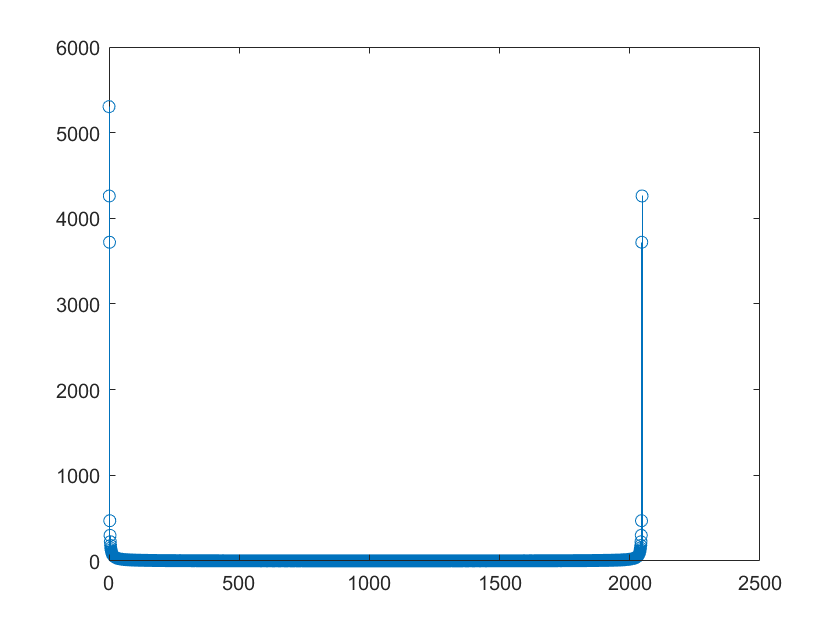

clear;
clf;
n=linspace(0,pi,2048);
x1=4*cos(1.2*pi*n+pi/3)+6*sin(0.4*pi*n-pi/6);
[xk,t]=dtfs0(x1);
magnitude=abs(xk);
stem(t,magnitude);

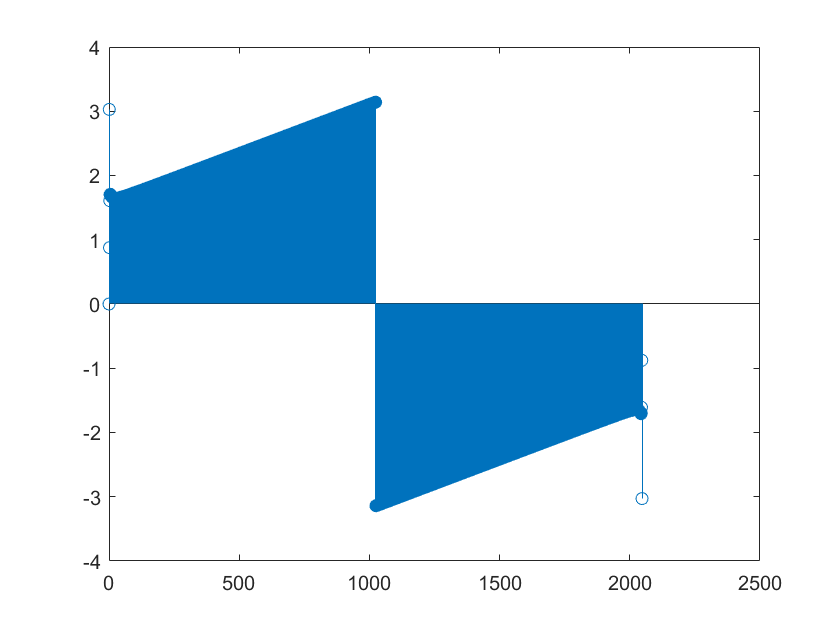

stem(t,angle(xk));

### (b)    x2[n] = {1, 1, 0, 1, 1, 1, 0, 1}, (one period)

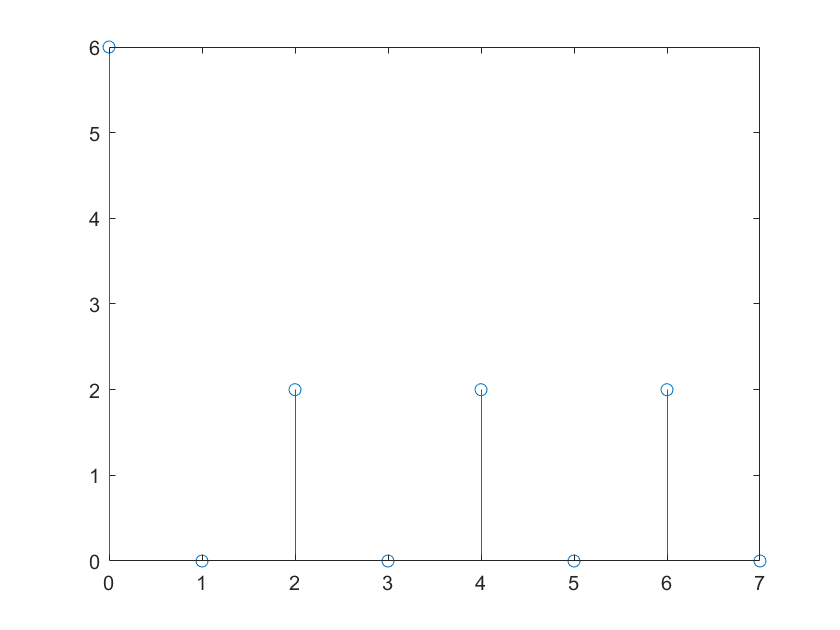

clear;
clf;
x2=[1 1 0 1 1 1 0 1];
[xk,t]=dtfs0(x2);
magnitude=abs(xk);
stem(t,magnitude);

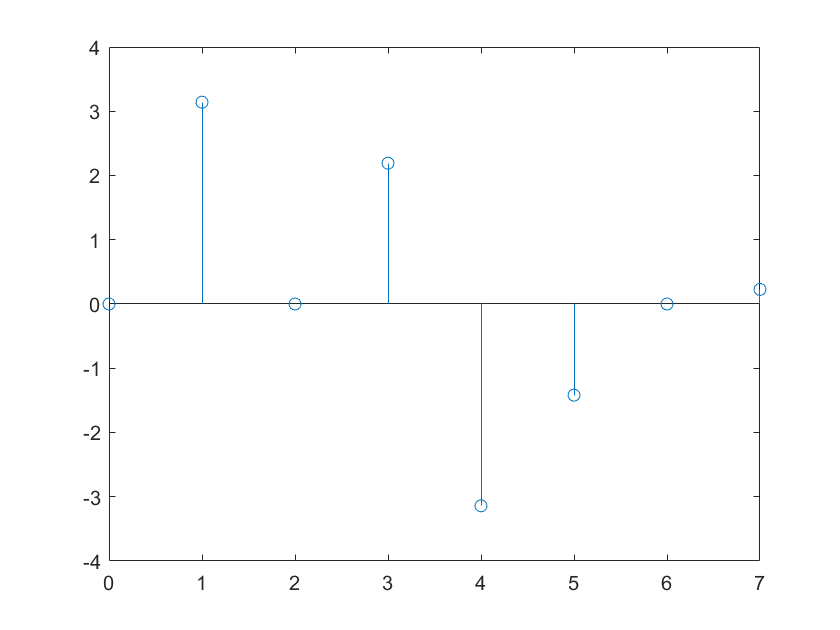

stem(t,angle(xk));

### (c)    x3[n] = 1 − sin( π 4 n), 0 ≤ n ≤ 11 (one period)

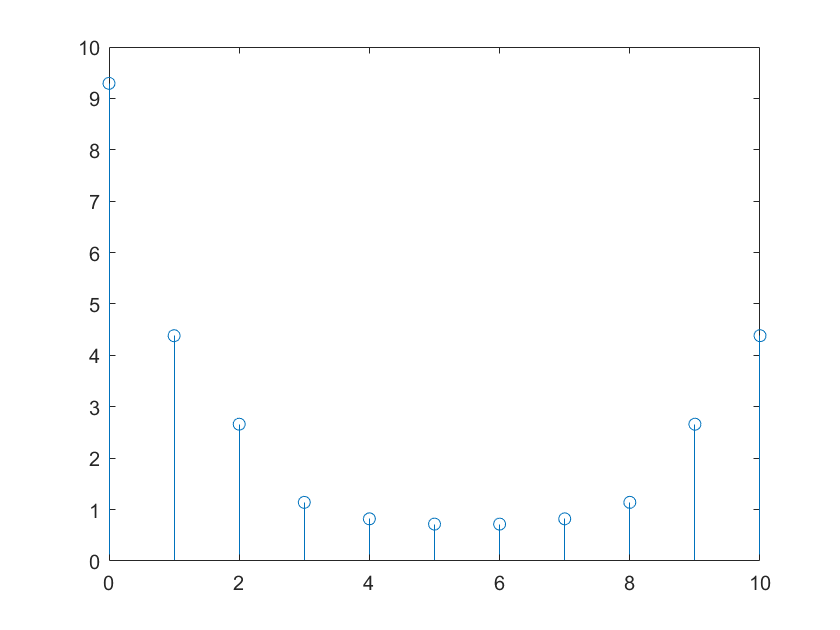

clear;
clf;

for i=0:10
    x3(i+1)=1-sin(i*pi/4);
end

[xk,t]=dtfs0(x3);
magnitude=abs(xk);
stem(t,magnitude);

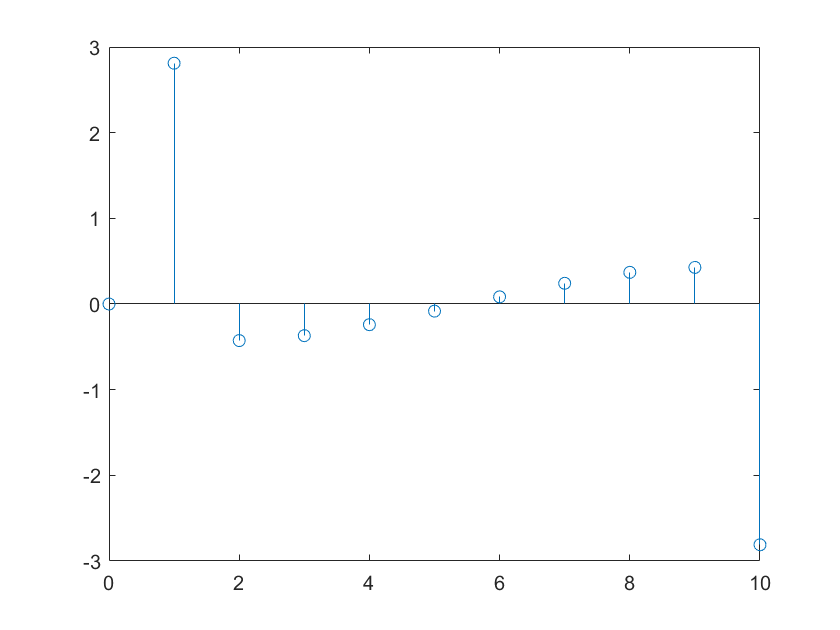

stem(t,angle(xk));

## Problem 8

### (a)    Use subplot to plot the magnitude |X1|, |X2| and phase ∠X1, ∠X2 in one graph respectively

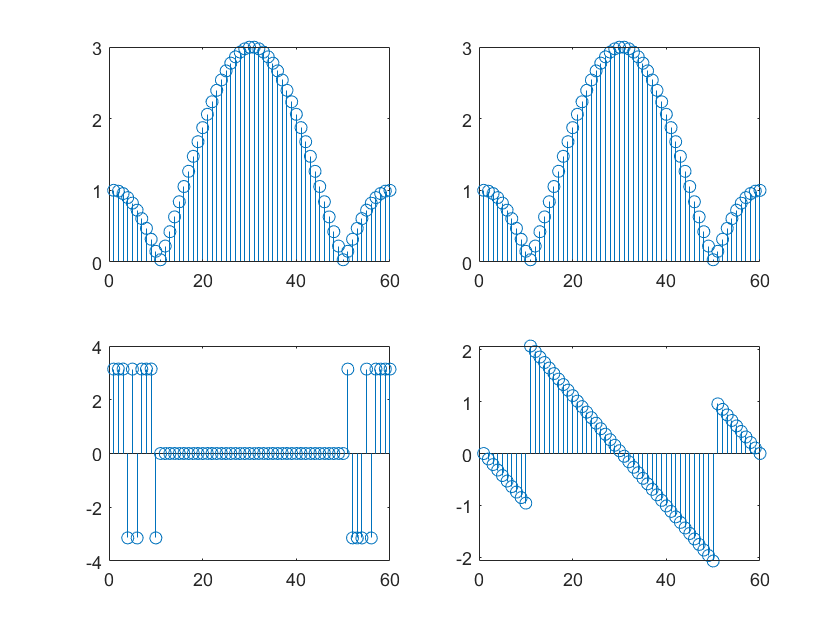

x=[1 1 1]; % n=-1,0,1
om=linspace(-pi, pi, 60);
X1=dtft12(x, -1, om); 
X2=freqz(x, 1, om);
subplot(2,2,1);
stem(abs(X1));
subplot(2,2,2);
stem(abs(X2));
subplot(2,2,3);
stem(angle(X1));
subplot(2,2,4);
stem(angle(X2));

### (b)    Is the magnitude |X1| = |X2| ? Is the phase ∠X1 = ∠X2 ? If not, Explain.

### from the result magnitude are the same but phase is different

### it easy to figure out that X1 sample different start point from X2

### so in frequency domain looks the same but have different phase

## Problem 9

### (a)    Consider the 5×5 impulse response h[m, n] given as follow: ℎ[𝑚, 𝑛] = { 1 25 , − 2 ≤ 𝑚, 𝑛 ≤ 2 0 , 𝑜𝑡ℎ𝑒𝑟𝑤𝑖𝑠𝑒 , filter the “DSP.png” using (2.78) and display the resulting image, comment on the result. (Hint: You can directly use conv2 function, and make sure the data format is double before filtering).

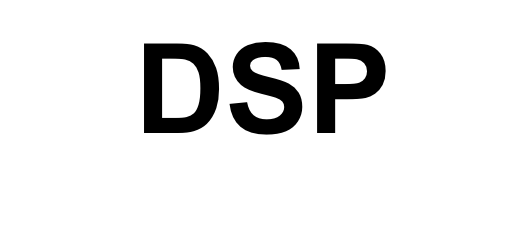

clear;
clf;
img = imread('DSP.png');
imshow(img);

imwrite(img, 'DSP0.png');


### (b)    Repeat part (a) and try two different kernels ℎ1 [𝑚, 𝑛] and ℎ2 [𝑚, 𝑛]

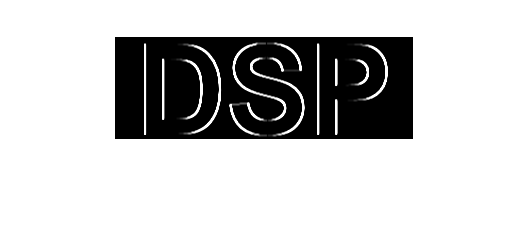

h1=[1 0 -1;2 0 -2;1 0 -1];
h2=[1 2 1;0 0 0;-1 -2 -1];
img_h1 = conv2(img,h1);
img_h2 = conv2(img,h2);
img_h1=uint8(abs(img_h1));
img_h2=uint8(abs(img_h2));
imshow(img_h1)

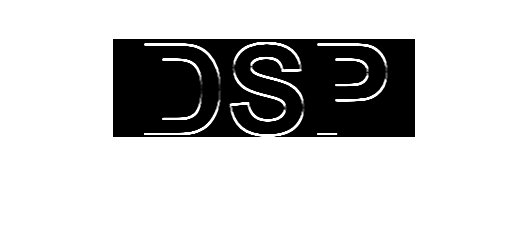

imshow(img_h2)

### (c)     Repeat (b) by using filter2 function, what is the difference between the two functions? (Hint: Check the pixel values before abs) 

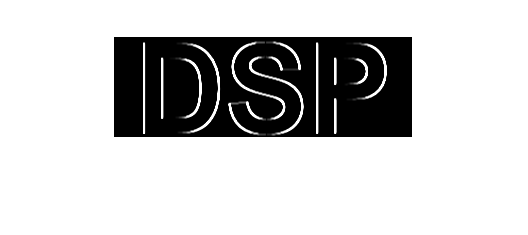

h1_filter2= filter2(h1,img);
h2_filter2= filter2(h2,img);

h1_filter2=uint8(abs(h1_filter2));
h2_filter2=uint8(abs(h2_filter2));
imshow(h1_filter2)

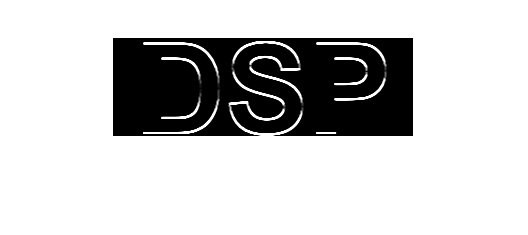

imshow(h2_filter2)

## Problem 10

### (a)    Select every other sample in audio signal y which reduces the sampling rate by a factor of two. 

[y,Fs] = audioread('handel.wav');

y_2 = downsample(y,2);
soundsc(y_2,Fs/2);
audiowrite('handel0_2.wav', y, Fs/2);

### (b)    Select every fourth sample in audio signal y which reduces the sampling rate by a factor of four. 

y_4 = downsample(y,4);
soundsc(y_4,Fs/4);
audiowrite('handel0_4.wav', y_4, Fs/4);

### (c)    From the results of (a) and (b), what do you discover?

### when down sample by 2 sounds awful.....

### when down sample by 4 sounds like shit (and sound a little bit like low pass filter)

### its beacuse the resolution is reduce it cant represent hi-end of a signal